# 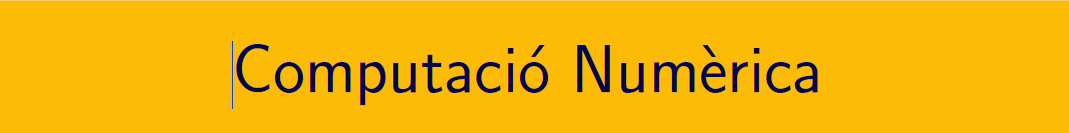

================================================================================

# Pràctica 11. Integració aproximada de funcions i dades.

`Document preparat per M. Àngela Grau Gotés - 12 de maig de 2021`

## Introducció

Exercicis del document MN_full9.pdf, el podeu trobar en el campus virtual. 

En la pràctica 10 de dimecres 5 de maig de 2021 vàrem treballar les fórmules d'integració simples i compostes 

- del punt mig (o rectangle)

- dels trapezis

- de Simpson

- romberg

## 1 RECORDEM .....

Obteniu una expressió analítica per a $\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\$

syms z f(z)
f(z) = exp(-z^2/2)

$$f(z) = {\mathrm{e}}^{-\frac{z^{2}}{2}}$$

ve = int(f(z),-1,1)

$$ve = \sqrt{2}\,\sqrt{\pi }\,\mathrm{erf}\left(\frac{\sqrt{2}}{2}\right)$$

### Exercici 1. Fórmules de Newton-Côtes compostes. Mètode Romberg.

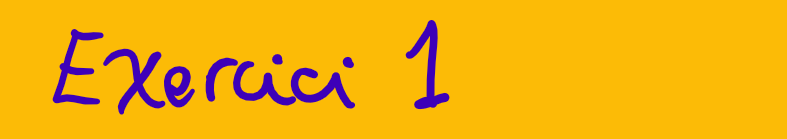

Bajarse el código de [romberg.m](http://www.math.mcgill.ca/gantumur/math578f09/matlab/romberg.m)

            
$$\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$$


- Valor exacte

clearvars
format shortG
a = -1; b = 1; 
f = @(x) exp(-x.^2/2);
I = sqrt(2*pi)*erf(sqrt(2)/2)   % I = integral(f,a,b)

I =        1.7112


- Mètode del punt mig, h=1,1/2,1/4,1/8,1/16. Exercici per verificar que P(h), P(h/2) ...  millora l'aproximació

% my_midp(f,a,b,0:6)
for k = 0:6
    n(k+1) = 2^k;   % intervals
    P(k+1) = midp(f,a,b,n(k+1));
end
disp(array2table([n; (b-a)./n; P; abs(P-I)]','VariableNames',{'n','h','Rectangle','error absolut'}))

    n        h       Rectangle    error absolut
    __    _______    _________    _____________

     1          2          2          0.28875  
     2          1      1.765         0.053745  
     4        0.5     1.7241         0.012824  
     8       0.25     1.7144        0.0031706  
    16      0.125      1.712       0.00079047  
    32     0.0625     1.7114       0.00019748  
    64    0.03125     1.7113       4.9362e-05  



- Mètode dels trapezis, h=1,1/2,1/4,1/8,1/16. Exercici per verificar que T(h), T(h/2) ...  millora l'aproximació

for k = 0:6
    n(k+1) = 2^k;
    T(k+1) = trap(f,a,b,n(k+1));
end
disp(array2table([n; (b-a)./n; T; abs(T-I)]','VariableNames',{'n','h','Trapecis','error absolut'}))

    n        h       Trapecis    error absolut
    __    _______    ________    _____________

     1          2     1.2131         0.49819  
     2          1     1.6065         0.10472  
     4        0.5     1.6858        0.025487  
     8       0.25     1.7049       0.0063312  
    16      0.125     1.7097       0.0015803  
    32     0.0625     1.7109      0.00039493  
    64    0.03125     1.7112      9.8722e-05  



- Regla de Simpson, h=1,1/2,1/4,1/8. Exercici per verificar que S(h), S(h/2) ...  millora l'aproximació

for k = 0:6
    n(k+1) = 2^k;
    S(k+1) = simp(f,a,b,n(k+1));
end
disp(array2table([n; (b-a)./n; S; abs(S-I)]','VariableNames',{'n','h','Simpson','error absolut'}))

    n        h       Simpson    error absolut
    __    _______    _______    _____________

     1          2    1.7377        0.026438  
     2          1    1.7122      0.00092397  
     4        0.5    1.7113      5.3851e-05  
     8       0.25    1.7113      3.3091e-06  
    16      0.125    1.7112      2.0595e-07  
    32     0.0625    1.7112      1.2859e-08  
    64    0.03125    1.7112      8.0345e-10  



- Mètode de Romberg, h=1,1/2,1/4,1/8,1/16

[R,h] = romberg(f,a,b,4);
[h',R]

ans =             2       1.2131            0            0            0
            1       1.6065       1.7377            0            0
          0.5       1.6858       1.7122       1.7105            0
         0.25       1.7049       1.7113       1.7112       1.7113


% ver video lab
[h',tril(abs(R-I))]

ans =             2      0.49819            0            0            0
            1      0.10472     0.026438            0            0
          0.5     0.025487   0.00092397   0.00077698            0
         0.25    0.0063312   5.3851e-05   4.1568e-06   8.1103e-06


[h',tril(fix(-log10(2*abs(R-I))))]

ans =             2            0            0            0            0
            1            0            1            0            0
          0.5            1            2            2            0
         0.25            1            3            5            4


### Exercici 2. Mètode de Montecarlo

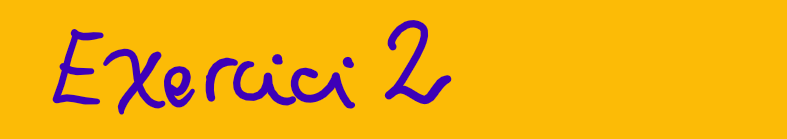

Calculeu el valor de    $\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$ 

- Tipus I (valor esperat)

a = -1; b =1; 
I = sqrt(2*pi)*erf(sqrt(2)/2)

I =        1.7112


g = @(x)(exp(-x.^2/2));
for k=1:5
    M(k) = 10^k;
    x = a+(b-a)*rand(M(k),1);
    y = g(x);,
    va(k) = (b-a)/M(k)*sum(y);
end
[1:k;M; va; abs(va-I) ]'

ans =             1           10       1.6534     0.057822
            2          100       1.7257     0.014473
            3         1000       1.7127    0.0014979
            4        10000       1.7118   0.00052506
            5        1e+05       1.7113   3.9685e-05


my_montecarlo(g,a,b,1:5);

    k      M       f(_)       error       xifres
    _    _____    ______    __________    ______

    1       10    1.9037       0.19241      0   
    2      100    1.7178     0.0065728      1   
    3     1000    1.6983      0.012903      1   
    4    10000    1.7128     0.0015255      2   
    5    1e+05    1.7103    0.00095184      2   



- Tipus II (hit or miss)

fplot(g,[-1,1],'Color','r','LineWidth',2), axis([-1,1,0,1]), hold on
a = -1; b = 1;
M = 10000;
x = a + (b-a)*rand(M,1);
y = rand(M,1);   % entre 0 a 1 mirant gràfica
v = y <= g(x);
V = sum(v);
valor_aproximat = V/M*(b-a)

valor_aproximat =          1.71


aprox = abs(I-valor_aproximat)

aprox =     0.0012488


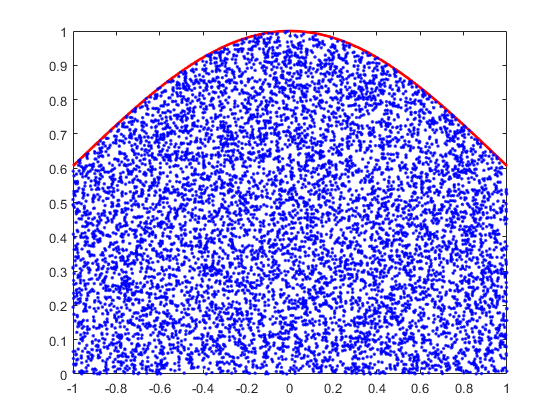

plot(x(v),y(v),'b.'), hold off

## 2 APRENEM .....

### Fórmules d'integració GAUSSIANA

Podeu descarregar els codis de MatLab File Exchange:   

- [Gaussian quadratures for several orthogonal polynomials](https://es.mathworks.com/matlabcentral/fileexchange/48144-gaussian-quadratures-for-several-orthogonal-polynomials) (Chebyshev)

- [Legendre Laguerre and Hermite - Gauss Quadrature](https://es.mathworks.com/matlabcentral/fileexchange/26737-legendre-laguerre-and-hermite-gauss-quadrature?s_tid=prof_contriblnk)

### Polinomis de Legendre

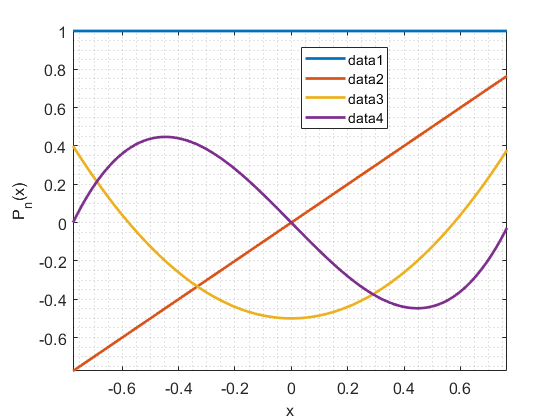

xi =       -0.7746
            0
       0.7746


w =       0.55556
      0.88889
      0.55556


clc,clf,clearvars
m = 3;
[xi, w] = gauss_quad(m,'legen')   % Felipe Uribe, Gaussian quadratures for several orthogonal polynomials 

[x2, w2] = GaussLegendre(m)    % Geert Van Damme, Legendre Laguerre and Hermite - Gauss Quadrature

x2 =       -0.7746
            0
       0.7746


w2 =       0.55556
      0.88889
      0.55556


### Polinomis de Chebyshev

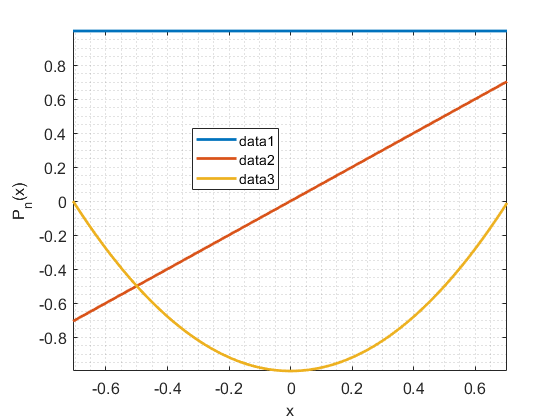

xi =      -0.70711
      0.70711


w =        1.5708
       1.5708


clc,clf,clearvars
m = 2;
[xi,w] = gauss_quad(m,'cheby')

### Exercici 3. Gauss Legendre

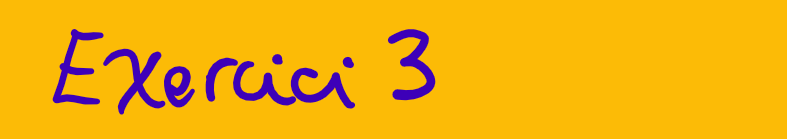

Calcular $\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$

- Valor exacte

clearvars
f = @(x) exp(-x.^2./2);
I = sqrt(2*pi)*erf(sqrt(2)/2)

I =        1.7112


- Fórmula de dos punts: m=2

m = 2;
[x2, w2] = GaussLegendre(m);
GL2 = sum(w2.*f(x2)), dc = abs(GL2-I)

GL2 =         1.693


dc =      0.018285


T = trap(f,-1,1,1), dc = abs(T-I)

T =        1.2131


dc =       0.49819


- Fórmula de tres punts: m=3

m = 3;
[x3, w3] = GaussLegendre(m);
GL3 = sum(w3.*f(x3)), dc = abs(GL3-I)

GL3 =         1.712


dc =    0.00077146


S = simp(f,-1,1,1), dc = abs(S-I)

S =        1.7377


dc =      0.026438


- Fórmula de quatre punts: m=4

m = 4;
[x4, w4] = GaussLegendre(m);
GL4 = sum(w4.*f(x4)), dc = abs(GL4-I)

GL4 =        1.7112


dc =    2.4279e-05


T = trap(f,-1,1,2), dc = abs(T-I)

T =        1.6065


dc =       0.10472


- Fórmula de cinc punts: m=5

m = 5;
[x5, w5] = GaussLegendre(m);
GL5 = sum(w5.*f(x5)), dc = abs(GL5-I)

GL5 =        1.7112


dc =    6.0974e-07


% S = simp(f,-1,1,2), dc = abs(S-I)

### Exercici 4. Gauss Chebyshev

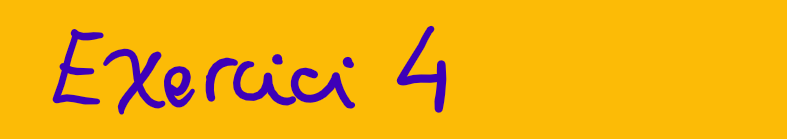

Calculeu el valor de    $$\quad\displaystyle  \int_{-1}^{1}\frac{\cos(\pi x)}{\sqrt{1-x^2}}dx $$ 

- Valor exacte

clc; clear variables; format compact;
format longG;
g = @(x) cos(pi*x);
f = @(x) cos(pi*x)./sqrt(1-x.^2);
I = integral(f,-1,1)

I =         -0.955804990198774

- Fórmula de dos punts: m=2. Compareu el valor calculat per trapezis (1interval=dos punts)

m = 2;
[xi,w] = GaussTxebixev_2(m);
GT2 = sum(w.*g(xi)), dc = abs(GT2-I)

GT2 =          -1.90286225269511

dc =          0.947057262496341

- Fórmula de tres punts: m=3.  Compareu el valor calculat per Simpson (1interval=tres punts)

m = 3;
[xi,w] = GaussTxebixev_2(m);
GT3 = sum(w.*g(xi)), dc = abs(GT3-I)

GT3 =         -0.864407539144361

dc =         0.0913974510544131

- Fórmula de quatre punts: m=4

m = 4;
[xi,w] = GaussTxebixev_2(m);
GT4 = sum(w.*g(xi)), dc = abs(GT4-I)

GT4 =         -0.960178853336925

dc =        0.00437386313815091

- Fórmula de cinc punts: m=5

m = 5;
[xi,w] = GaussTxebixev_2(m);
GT5 = sum(w.*g(xi)), dc = abs(GT5-I)

GT5 =         -0.955678729764403

dc =       0.000126260434370362

### Exercici 5. Canvi interval

## 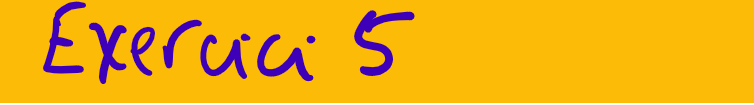

 Calculeu el valor de $  I=\displaystyle\int_{1}^{2} \ln(x)\,dx $ fent ús de fórmules de Gauss-Legendre. Obseveu que el canvi d'interval és $  I=\displaystyle\int_{1}^{2} \ln(x)\,dx = \frac{1}{2}\int_{-1}^{1} \ln\Big(\frac{t+3}{2}\Big)\,dt \,.$

f = @(x) log(x);
a = 1; b = 2;
ve = integral(f,a,b)

ve =       0.38629

g = @(x) log((x+3)/2);
m = 4;
[x4, w4] = GaussLegendre(m);
GL4 = 1/2*sum(w4.*g(x4)), Gerror = abs(GL4-ve)

GL4 =       0.38629

Gerror =    1.3582e-07

## 3 PRACTIQUEM ....

### Pràctica 26. Integració gaussiana de dos punts.

Fent ús d'una fórmula d'integració gaussiana de dos punts calculeu:

- 
$$$ \rm{a)}\quad\displaystyle\int_{-1}^{1}e^xdx $$$
 

f = @(x) exp(x);
ve = integral(f,-1,1)

ve =        2.3504


m = 2;
[x2 w2] = GaussLegendre(m);
GL2 = sum(w2.*f(x2)), Gerror = abs(GL2-ve)

GL2 =        2.3427


Gerror =     0.0077063


- 
$$$\rm{b)}\quad\displaystyle \int_{0}^{1}(7+14x^6)dx $$$


f = @(x) 7+14*x.^6;
ve = integral(f,0,1)

ve =             9


g = @(t) 1/2*f((1+t)/2);    
m = 2;
[x2 w2] = GaussLegendre(m);
GL2 = sum(w2.*g(x2)), Gerror = abs(GL2-ve)

GL2 =        8.6852


Gerror =       0.31481


- 
$$$\rm{c)}\quad\displaystyle \int_{0}^{3}x^2e^{x} dx $$$


f = @(x) x.^2.*exp(x);
ve = integral(f,0,3)

ve =        98.428


g = @(t) 3/2*f((3+3*t)/2);   
m = 2;
[x2 w2] = GaussLegendre(m);
GL2 = sum(w2.*g(x2)), Gerror = abs(GL2-ve)

GL2 =        90.607


Gerror =        7.8203


### Pràctica 26. Integració gaussiana de quatre punts.

Fent ús d'una fórmula d'integració gaussiana de quatre punts calculeu:

- 
$$$\rm{a)}\quad\displaystyle \int_{-1}^{1}cos(x) dx $$$


f = @(x) cos(x);
ve = integral(f,-1,1)

ve =        1.6829

m = 4;
[x4 w4] = GaussLegendre(m);
GL4= sum(w4.*f(x4)), Gerror = abs(GL4-ve)

GL4 =        1.6829

Gerror =    2.8092e-07

- 
$$$\rm{b)}\quad\displaystyle \int_{-1}^{1}e^xdx $$$


f = @(x) exp(x);
ve = integral(f,-1,1)

ve =        2.3504

m = 4;
[x4 w4] = GaussLegendre(m);
GL4= sum(w4.*f(x4)), Gerror = abs(GL4-ve)

GL4 =        2.3504

Gerror =    2.9513e-07

- $$\rm{c)}\quad\displaystyle \int_{0}^{1}\ln(x)sin^2(x)dx $$  (Canvi d'interval)

f = @(x) log(x).*sin(x).^2;
ve = integral(f,0,1)

ve =     -0.098647

g = @(t) 1/2*f((1+t)/2);
m = 4;
[x4 w4] = GaussLegendre(m);
GL4= sum(w4.*g(x4)), Gerror = abs(GL4-ve)

GL4 =       -0.0986

Gerror =    4.6782e-05

- $$\rm{d)}\quad\displaystyle \int_{0}^{1}\ln(1+\cos(x))dx $$  (Canvi d'interval)

f = @(x) log(1+cos(x));
ve = integral(f,0,1)

ve =       0.60763

g = @(t) 1/2*f((1+t)/2);
m = 4;
[x4 w4] = GaussLegendre(m);
GL4= sum(w4.*g(x4)), Gerror = abs(GL4-ve)

GL4 =       0.60763

Gerror =    2.7399e-09

### Pràctica 26. Integració per Gauss-Chebyschev.

Calculeu les integrals següents per Gauss-Txebisxev, per m=2, 3, 4 i 5 punts


$$$\rm{a)}\quad\displaystyle  \int_{-1}^{1}\frac{x^2}{\sqrt{1-x^2}}dx $$$


f = @(x) x.^2./sqrt(1-x.^2);
g = @(x) x.^2;
I = integral(f,-1,1)

I =        1.5708


GT = []; k = 1; GTe = [];
for m = 2:5
   [xi,w] = GaussTxebixev_2(m);
   GT(k) = sum(w.*g(xi));
   GTe(k) = abs(GT(k)-I);
   k = k + 1;
end
disp(array2table([(2:5)',GT',GTe'],'VariableNames',{'m','GT','error'}));

    m      GT        error   
    _    ______    __________

    2    1.5708    7.2164e-14
    3    1.5708    7.2387e-14
    4    1.5708    7.2164e-14
    5    1.5708    7.2164e-14




$$$\rm{b)}\quad\displaystyle  \int_{-1}^{1}\frac{\cos(\pi x)}{\sqrt{1-x^2}}dx $$$


f = @(x) cos(pi.*x)./sqrt(1-x.^2);
g = @(x) cos(pi.*x);
I = integral(f,-1,1)

I =       -0.9558


GT = []; k = 1; GTe = [];
for m = 2:5
   [xi,w] = GaussTxebixev_2(m);
   GT(k) = sum(w.*g(xi));
   GTe(k) = abs(GT(k)-I);
   k = k + 1;
end
disp(array2table([(2:5)',GT',GTe'],'VariableNames',{'m','GT','error'}));

    m       GT         error   
    _    ________    __________

    2     -1.9029       0.94706
    3    -0.86441      0.091397
    4    -0.96018     0.0043739
    5    -0.95568    0.00012626



$$\rm{c)}\quad\displaystyle  \int_{0}^{1}\frac{x^2}{\sqrt{x(1-x)}}dx $$ (Canvi d'interval)

f = @(x) x.^2./sqrt(x.*(1-x));
g = @(x) x.^2;
fg = @(x) g((1+x)/2);
I = integral(f,0,1)

I =        1.1781


% malament
GT = []; k = 1; GTe = [];
for m = 2:5
   [xi,w] = GaussTxebixev_2(m);
   GT(k) = sum(w.*fg(xi));
   GTe(k) = abs(GT(k)-I);
   k = k + 1;
end
disp(array2table([(2:5)',GT',GTe'],'VariableNames',{'m','GT','error'}));

    m      GT        error   
    _    ______    __________

    2    1.1781    1.5032e-13
    3    1.1781     1.501e-13
    4    1.1781    1.5032e-13
    5    1.1781    1.5055e-13

